# Test 1 - Multivariable Control ME-422

**Student names: ***[COMPLETE WITH YOUR NAMES!!!]*

1)

2) 

3) 

***Info: ****The test is open books, open notes.*

*Once you finished the test, compress the following files into a single zip file:*

- *'Test1.mlx',*

- *Simulink model(s),*

- *'motor_func.m' and any auxiliary *`.m`* files you might have created,*

*Name the file "TEST_1_GROUP_xx.zip", where 'xx' is the group number. Then, upload the zip file on Moodle.*

## **Simulink Modeling, Linearization and Stability Analysis**

clc
clear all

In this test, we will consider a separately excited DC motor.

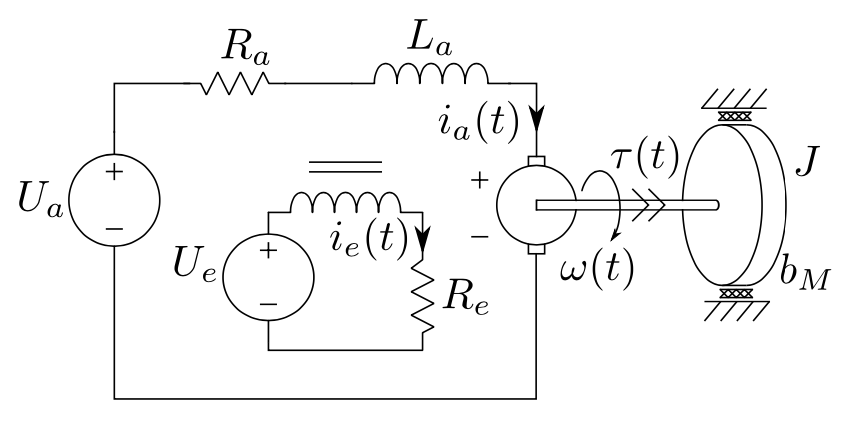

The dynamics of the system can be modeled by the following nonlinear state-space equations:


$${\dot{x} }_1 \left(t\right)=\frac{1}{L_a }\left(u_1 \left(t\right)-R_a \;x_1 \left(t\right)-K_m \;x_2 \left(t\right)\;x_3 \left(t\right)\right)$$



$${\dot{x} }_2 \left(t\right)=u_2 \left(t\right)-R_e {\;g}^{-1} \left(x_2 \left(t\right)\right)$$



$${\dot{x} }_3 \left(t\right)=\frac{1}{J}\left(K_m \;x_1 \left(t\right)\;x_2 \left(t\right)-b_m \;x_3 \left(t\right)\right)$$


where ${\;g}^{-1} \left(\cdot \;\right)$ is the inverse function of the field characteristic and is given by

$g^{-1} \left(x\right)=7\cdot \mathrm{atanh}\left(\frac{x}{550}\right)$.

The **control inputs** are

- $u_1 \left(t\right)=U_a \left(t\right)$ the armature voltage [V],

- $u_2 \left(t\right)=U_e \left(t\right)$ the excitation voltage [V].

The **states** are

- $x_1 \left(t\right)=\;i_a \left(t\right)$ the armature current [A], 

- $x_2 \left(t\right)=\phi_e \left(t\right)$ the magnetic flux in field winding of the excitation circuit [Wb], 

- $x_3 \left(t\right)=\omega \left(t\right)$ the angular velocity [rad/s]. 

For the **outputs**, we consider the armature current and angular velocity, in rpm (revolutions per minute):

- $y_1 \left(t\right)=x_1 \left(t\right)$,

- $y_2 \left(t\right)=\frac{60}{2\pi \;}x_3 \left(t\right)$.

The **parameter values** are given by:

La = 0.003;  % [H]
Ra = 0.05;   % [Ohms]
Km = 0.016;  % (unitless)
Re = 25.2;   % [Ohms]
J = 15;      % [kg m^2]
bm = 1.1;    % [N m s]

1) Implement the nonlinear model of the system in Simulink, and save it as `motor.slx`.

You may use the MATLAB function `motor_func.m`, which takes as input the control inputs, states and parameter values and computes the time derivatives of states in the nonlinear system above.

*Hint: Implement the state dynamics first. Once you have implemented the state dynamics, add the output equations to the Simulink model.*

2) Assume that the system is initialized at zero:

x1_ini = 0;   % i_a
x2_ini = 0;   % phi_e
x3_ini = 0;   % omega

Simulate the evolution of the system when the following control input is applied:


$$u_1(t) =
\begin{cases}
0 & \text{if } 0 \leq t < 10, \\
\frac{\bar{U}_a}{10} (t-10) & \text{if } 10 \leq t < 20, \\
\bar{U}_a & \text{if } t \geq 20,
\end{cases}$$


$u_2 \left(t\right)={\bar{U} }_e$,

with ${\bar{U} }_a =460\;V$ and ${\bar{U} }_e =184\;V$.

*Hint: Implement the control input *$u_1 \left(t\right)$* in Simulink as the sum of two Ramp blocks with positive and negative slope.*

Ua_bar = 460;
Ue_bar = 184;
% Insert your code here for running the simulation in Simulink


a) Plot the input and output trajectories in this live script by importing the data from Simulink.

% Insert your code here


b) Plot the state trajectories in this live script by importing the data from Simulink.

% Insert your code here


3) Find the equilibrium state when a constant input of $\bar{u} ={\left\lbrack {\bar{U} }_a ,{\bar{U} }_e \right\rbrack }^{\top }$ is applied **by simulating the system and analyzing the trajectories.**

*Hint: Note that *$\bar{u}$* is the input applied in question 2 after *$t=20\;s$*.*

% Insert your code here.
% we want to solve 0 = Ax_bar + Bu0

%we try with A and B : 


% u0 after 20 s -> U_barA = 460 V and U_barE = 184 
u1 = Ua_bar;
u2 = Ue_bar;

g = @(x2) 7 * atanh(x2 / 550);

f = @(x) [ (1/La)*(u1 - Ra*x(1) - Km*x(1)*x(2));
            u2 - Re*g(x(2));
            1/J*(Km*x(1)*x(2)-bm*x(3))];

x0 = [0;0;0];
x_bar = fsolve(f, x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.




x1_bar = x_bar(1);
x2_bar = x_bar(2);
x3_bar = x_bar(3);


fprintf("The equilibrium state is given by \n" + ...
"x1_bar = %.2f A, \nx2_bar = %.2f Wb, \nx3_bar = %.2f rad/s.", x1_bar, x2_bar, x3_bar);

The equilibrium state is given by 
x1_bar = 66.61 A, 
x2_bar = 428.51 Wb, 
x3_bar = 415.15 rad/s.

4) Linearize the system around the computed equilibrium.

*Hint: Use the Timed-Based Linearization block, selecting the appropriate inputs and outputs.*

% Insert your code here

% sys.A = ...;
% sys.B = ...;
% sys.C = ...;
% sys.D = ...;

fprintf("The linearized system is given by:");

The linearized system is given by:

sys_lin = ss(sys.A, sys.B, sys.C, sys.D)

Unable to resolve the name 'sys.A'.

5) [Bonus point]

a) Analyze the stability of the linearized system.

b) Can you conclude anything about the stability of the equilibrium of the nonlinear system?

% If needed, insert your code here:
% we need to analyse the eigen value of A linearized for discret time if
% the module is in the circile egal to one, and for continous time, if the
% real part is in inferior to zero for all eigenvalue
% we are in continous time model

% (a)

eigen_value = eig(A);

if all(real(eigen_value) < 0)
    disp('the system is stable');
else
    disp('the system is unstable');
end

% (b)

*Anwser:*